Gss =
 
  A = 
            theta    omega
   theta        0        1
   omega  -0.8957   -3.334
 
  B = 
              u1
   theta       0
   omega  0.9745
 
  C = 
          theta  omega
   theta      1      0
 
  D = 
          u1
   theta   0
 
Continuous-time state-space model.



Gss2 =
 
  A = 
             Velocity  Position
   Velocity    -3.334   -0.8957
   Position         1         0
 
  B = 
             u1
   Velocity   1
   Position   0
 
  C = 
             Velocity  Position
   Position         0    0.9745
 
  D = 
             u1
   Position   0
 
Continuous-time state-space model.



Agorro =    -3.3340   -1.0998
    1.0000    2.0834


Bgorro =    -0.2094    1.0000
    2.1378         0


Cgorro =          0    0.9745


Obs =
 
  A = 
              velocidad   posición
   velocidad     -3.334       -1.1
   posición           1      2.083
 
  B = 
                theta      PWM
   velocidad  -0.2094        1
   posición     2.138        0
 
  C = 
             velocidad   posición
   posición          0     0.9745
 
  D = 
             theta    PWM
   posición      0      0
 
Continuous-time state-space model.



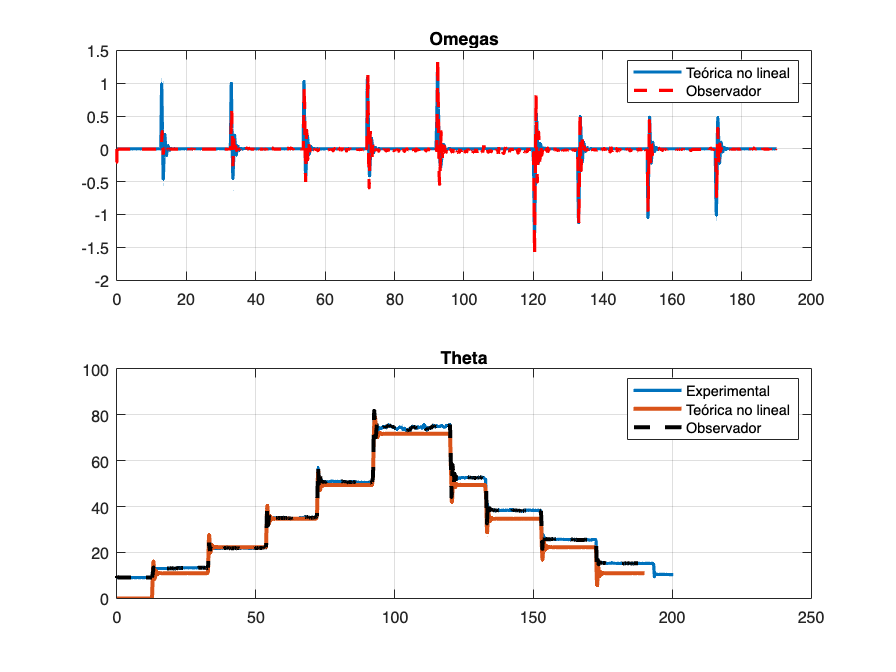

clear; close all; clc; 
addpath("data/");

load("DatosStepsVariables.mat"); 
theta_0 = 89;  % inicial
[sys, ~, ~, ~] = FoundTF(theta_0); 
load("data/TF.mat"); 

% Variables de estado 
A = sys.A; 
B = sys.B; 
C = sys.C; 
D = sys.D; 

% Matrices de ponderacion 
qx1 = 100; 
qx2 = 1000000; 
r = 1; 

Q = [qx1 0  ;0 qx2];
R = r; 

% Diseño de lqr 
[L, S, P] = lqr(A', C', Q, R); 
L = L'; 

data = sim("observer", 190); % Simulacion 

t = data.tout; 
% Velocities
omega = data.omega.Data ; 
omega_hat = data.omega_hat.Data; 

% Angles 
theta = data.theta.Data ; 
theta_hat = data.theta_hat.Data ; 
theta_exp = data.theta_exp.Data; 

subplot(2, 1, 1); 
plot(t, omega, t, omega_hat, "r--", "LineWidth", 2); 
title("Omegas")
legend("Teórica no lineal", "Observador"); 
grid on; 

subplot(2, 1, 2); 
plot(DatosStepsVariables(:,1), DatosStepsVariables(:,3), "LineWidth", 2); 

hold on; 
plot(t, theta, t, theta_hat, "k--", "LineWidth", 2.5); 
hold off; 

title("Theta")
legend("Experimental", "Teórica no lineal", "Observador" ); 
grid on; 